# **Finding the eigenvalues**

Find the eigenvalues of hilb(4) and generate a semilogy plot. 

**1. Initializing**

A = hilb(4); % Must be symmetric

m = length(A);
logvector = [];

**2. Tridiagonalization and Iteration**

Tridiagonalizing the given matrix and finding the eigenvalues of A by QR Algorithm without shifts.

T = tridiag(A);
eigenvalues = zeros(m, 1); % vector for saving eigenvalues of A
% Finding the eigenvalue approximately by mth to 1st column's of Q^(iter) of A
for k = m:-1:2 % 
    [T, eigenvalue, log] = qralg_verb(T(1:k, 1:k));
    eigenvalues(k) = eigenvalue; 
    logvector = [logvector, log]; % Appending the log
end
logvector = [logvector, T(2,1)]; % Note that iteration
eigenvalues(1) = T(1,1);

**3. Semilogy plot**

figure
format = [' The eigenvalues are: [', repmat('%f, ', 1, numel(eigenvalues')-1), '%f]  \n'];
fprintf(format, eigenvalues');  % print the approximated eigenvalues 

 The eigenvalues are: [1.500214, 0.169141, 0.006738, 0.000097]  


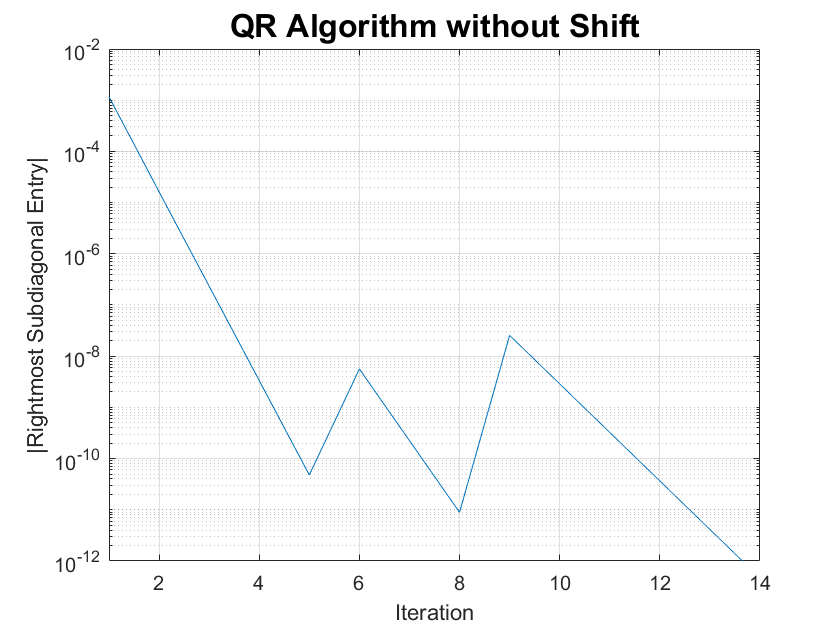


% Plot the result
semilogy(1:length(logvector),logvector)
title('QR Algorithm without Shift','fontweight','bold','fontsize',16)
xlabel('Iteration'), ylabel('|Rightmost Subdiagonal Entry|')
xlim([1 length(logvector)]), ylim([10^-12 10^-2])
grid on
saveas(gcf,'Plot.pdf') % Save the resulting plot